%% ========================================================================
%  RIS BEAM-STEERING LIMITATION AND ARRAY-SCALING STUDY
%
%  PURPOSE
%  -------
%  This script investigates whether the present 2.45 GHz 1-bit RIS
%  can produce a well-defined steered beam.
%
%  The analysis uses the ACTUAL HFSS unit-cell response:
%
%       ON  phase  = +148.922 deg
%       OFF phase  = -70.255 deg
%       ON  magnitude  = 0.8447
%       OFF magnitude = 0.8599
%
%  The study is intentionally separated from the later ESP32
%  signal-improvement study.
%
%  STAGE 1 QUESTIONS
%  -----------------
%
%  1. What beams can the 4x4 binary aperture actually produce?
%  2. Can a requested 20-degree beam be produced accurately?
%  3. How broad is the resulting beam?
%  4. What happens when the aperture is increased?
%  5. How does physical aperture and far-field distance scale?
%
%  ARRAY SIZES:
%       2x2
%       4x4
%       8x8
%       10x10
%       16x16
%       64x64
%       256x256
%       512x512
%
%  NOTE:
%  256x256 and 512x512 are analytical scaling cases.
%  Their physical dimensions become many metres at 2.45 GHz.
%
% ========================================================================

clear;
clc;
close all;

fprintf('\n');
fprintf('====================================================================\n');

fprintf('       2.45 GHz RIS BEAM-STEERING LIMITATION STUDY\n');

       2.45 GHz RIS BEAM-STEERING LIMITATION STUDY


fprintf('====================================================================\n');



%% ========================================================================
% 1. FREQUENCY AND WAVELENGTH
% ========================================================================

f = 2.45e9;                     % Hz
c = 299792458;                  % m/s

lambda = c/f;
k = 2*pi/lambda;

fprintf('\n');
fprintf('ELECTROMAGNETIC PARAMETERS\n');

ELECTROMAGNETIC PARAMETERS


fprintf('--------------------------------------------------------------------\n');

--------------------------------------------------------------------


fprintf('Frequency                  = %.3f GHz\n',f/1e9);

Frequency                  = 2.450 GHz


fprintf('Wavelength                 = %.3f mm\n',lambda*1e3);

Wavelength                 = 122.364 mm


fprintf('Wave number                = %.4f rad/m\n',k);

Wave number                = 51.3482 rad/m




%% ========================================================================
% 2. ACTUAL HFSS UNIT-CELL PARAMETERS
% ========================================================================

cellX = 40e-3;                  % 40 mm
cellY = 40e-3;                  % 40 mm

pitchX = 61e-3;                 % 61 mm
pitchY = 61e-3;                 % 61 mm

phaseON_deg  = +148.9220;
phaseOFF_deg = -70.2555;

magON  = 0.8447;
magOFF = 0.8599;

phaseON  = deg2rad(phaseON_deg);
phaseOFF = deg2rad(phaseOFF_deg);

% Only the relative phase matters for the array factor.
phaseDifference = ...
    angle(exp(1j*(phaseON-phaseOFF)));

phaseDifference_deg = rad2deg(phaseDifference);

fprintf('\n');
fprintf('ACTUAL HFSS UNIT-CELL RESPONSE\n');

ACTUAL HFSS UNIT-CELL RESPONSE


fprintf('--------------------------------------------------------------------\n');

--------------------------------------------------------------------



fprintf('Unit-cell size             = %.1f x %.1f mm\n', ...
    cellX*1e3,cellY*1e3);

Unit-cell size             = 40.0 x 40.0 mm



fprintf('Element pitch              = %.1f x %.1f mm\n', ...
    pitchX*1e3,pitchY*1e3);

Element pitch              = 61.0 x 61.0 mm



fprintf('Pitch / wavelength         = %.4f lambda\n', ...
    pitchX/lambda);

Pitch / wavelength         = 0.4985 lambda



fprintf('ON phase                   = %+8.4f deg\n', ...
    phaseON_deg);

ON phase                   = +148.9220 deg



fprintf('OFF phase                  = %+8.4f deg\n', ...
    phaseOFF_deg);

OFF phase                  = -70.2555 deg



fprintf('Circular phase difference  = %+8.4f deg\n', ...
    phaseDifference_deg);

Circular phase difference  = -140.8225 deg



fprintf('ON magnitude               = %.4f\n',magON);

ON magnitude               = 0.8447


fprintf('OFF magnitude              = %.4f\n',magOFF);

OFF magnitude              = 0.8599




%% ========================================================================
% 3. ARRAY SIZES
% ========================================================================

arraySizes = [2 4 8 16 64 256 512];

fprintf('\n');
fprintf('ARRAY-SCALING CASES\n');

ARRAY-SCALING CASES


fprintf('--------------------------------------------------------------------\n');

--------------------------------------------------------------------



for n = 1:length(arraySizes)

    N = arraySizes(n);

    D = ...
        (N-1)*pitchX + cellX;

    farFieldDistance = ...
        2*D^2/lambda;

    fprintf( ...
        '%3dx%-3d   Elements = %-8d   Physical size = %8.3f m   ', ...
        N,N,N^2,D);

    fprintf( ...
        'Far-field distance = %8.3f m\n', ...
        farFieldDistance);

end

  2x2     Elements = 4          Physical size =    0.101 m   

Far-field distance =    0.167 m


  4x4     Elements = 16         Physical size =    0.223 m   

Far-field distance =    0.813 m


  8x8     Elements = 64         Physical size =    0.467 m   

Far-field distance =    3.565 m


 16x16    Elements = 256        Physical size =    0.955 m   

Far-field distance =   14.907 m


 64x64    Elements = 4096       Physical size =    3.883 m   

Far-field distance =  246.439 m


256x256   Elements = 65536      Physical size =   15.595 m   

Far-field distance = 3975.082 m


512x512   Elements = 262144     Physical size =   31.211 m   

Far-field distance = 15921.748 m




%% ========================================================================
% 4. ANGULAR GRID
% ========================================================================

theta = -90:0.05:90;


%% ========================================================================
% 5. TARGET STEERING ANGLE
% ========================================================================

targetAngle = 20;

fprintf('\n');
fprintf('TARGET STEERING ANGLE\n');

TARGET STEERING ANGLE


fprintf('--------------------------------------------------------------------\n');

--------------------------------------------------------------------


fprintf('Target angle = %+6.2f deg\n',targetAngle);

Target angle = +20.00 deg




%% ========================================================================
% 6. 4x4 EXHAUSTIVE BINARY CODEBOOK
%
% There are only:
%
%             2^4 = 16
%
% possible X-direction binary patterns.
%
% Every column is repeated along Y.
%
% Therefore this is an EXHAUSTIVE physical codebook for the
% X-Z steering plane of the 4x4 RIS.
% ========================================================================

N = 4;

numPatterns = 2^N;

codebookPattern = zeros(numPatterns,N);
codebookBeam    = zeros(numPatterns,1);
codebookBW      = zeros(numPatterns,1);
codebookPeak    = zeros(numPatterns,1);

all4x4AF = cell(numPatterns,1);


for p = 0:numPatterns-1

    % Binary pattern
    bits = bitget(p,N:-1:1);

    codebookPattern(p+1,:) = bits;


    % ------------------------------------------------------------
    % Physical state assignment
    % ------------------------------------------------------------

    phaseColumn = ...
        phaseOFF*ones(1,N);

    magnitudeColumn = ...
        magOFF*ones(1,N);

    phaseColumn(bits==1) = phaseON;
    magnitudeColumn(bits==1) = magON;


    % ------------------------------------------------------------
    % X coordinates
    % ------------------------------------------------------------

    x = ...
        ((0:N-1)-(N-1)/2)*pitchX;


    % ------------------------------------------------------------
    % Array factor
    %
    % The minus sign is selected to match the theta convention
    % used in the previous MATLAB/HFSS comparison:
    %
    %       0011 -> approximately +18 deg
    %       1100 -> approximately -18 deg
    %
    % If your HFSS theta convention is opposite, reverse this sign.
    % ------------------------------------------------------------

    AF = zeros(size(theta));

    for t = 1:length(theta)

        steeringPhase = ...
            -k*x*sind(theta(t));

        AF(t) = ...
            sum( ...
            magnitudeColumn .* ...
            exp(1j*(phaseColumn + steeringPhase)));

    end


    % ------------------------------------------------------------
    % Normalize
    % ------------------------------------------------------------

    AFmag = abs(AF);

    AFdB = ...
        20*log10( ...
        AFmag/max(AFmag) + 1e-12);

    all4x4AF{p+1} = AFdB;


    % ------------------------------------------------------------
    % Global maximum
    % ------------------------------------------------------------

    [peak,idx] = max(AFmag);

    codebookBeam(p+1) = theta(idx);
    codebookPeak(p+1) = peak;


    % ------------------------------------------------------------
    % 3-dB beamwidth
    %
    % Find the contiguous region around the GLOBAL maximum.
    % ------------------------------------------------------------

    peakIndex = idx;

    leftIndex = peakIndex;

    while leftIndex > 1 && ...
            AFdB(leftIndex-1) >= -3

        leftIndex = leftIndex-1;

    end

    rightIndex = peakIndex;

    while rightIndex < length(theta) && ...
            AFdB(rightIndex+1) >= -3

        rightIndex = rightIndex+1;

    end

    codebookBW(p+1) = ...
        theta(rightIndex)-theta(leftIndex);

end


%% ========================================================================
% 7. PRINT 4x4 CODEBOOK
% ========================================================================

fprintf('\n');
fprintf('====================================================================\n');

fprintf('                    4x4 BINARY CODEBOOK\n');

                    4x4 BINARY CODEBOOK


fprintf('====================================================================\n');


fprintf('\n');
fprintf('Pattern       Beam Angle       3-dB Beamwidth\n');

Pattern       Beam Angle       3-dB Beamwidth


fprintf('--------------------------------------------------------------------\n');

--------------------------------------------------------------------



for p = 1:numPatterns

    bits = codebookPattern(p,:);

    fprintf( ...
        '%d%d%d%d          %+8.2f deg        %8.2f deg\n', ...
        bits(1),bits(2),bits(3),bits(4), ...
        codebookBeam(p), ...
        codebookBW(p));

end

0000             +0.00 deg           26.30 deg
0001            -13.60 deg           28.35 deg
0010            +45.40 deg           46.20 deg
0011            -18.05 deg           26.40 deg
0100            -45.40 deg           46.20 deg
0101            -73.45 deg           42.35 deg
0110            -37.90 deg           31.10 deg
0111            -13.75 deg           27.95 deg
1000            +13.60 deg           28.35 deg
1001            -37.75 deg           31.35 deg
1010            +73.45 deg           42.35 deg
1011            +45.40 deg           47.05 deg
1100            +18.05 deg           26.40 deg
1101            -45.40 deg           47.05 deg
1110            +13.75 deg           27.95 deg
1111             +0.00 deg           26.30 deg




%% ========================================================================
% 8. FIND BEST 4x4 PATTERN FOR 20 DEG
% ========================================================================

angleError = ...
    abs(codebookBeam-targetAngle);

[bestError,bestIndex] = min(angleError);

bestPattern = ...
    codebookPattern(bestIndex,:);

bestBeam = ...
    codebookBeam(bestIndex);

bestBW = ...
    codebookBW(bestIndex);

fprintf('\n');
fprintf('====================================================================\n');

fprintf('              4x4 TARGET FEASIBILITY\n');

              4x4 TARGET FEASIBILITY


fprintf('====================================================================\n');


fprintf('\n');

fprintf('Requested beam           = %+8.2f deg\n',targetAngle);

Requested beam           =   +20.00 deg



fprintf('Best binary pattern      = %d%d%d%d\n', ...
    bestPattern(1), ...
    bestPattern(2), ...
    bestPattern(3), ...
    bestPattern(4));

Best binary pattern      = 1100



fprintf('Actual dominant beam     = %+8.2f deg\n',bestBeam);

Actual dominant beam     =   +18.05 deg



fprintf('Pointing error            = %+8.2f deg\n', ...
    bestBeam-targetAngle);

Pointing error            =    -1.95 deg



fprintf('3-dB beamwidth            = %+8.2f deg\n',bestBW);

3-dB beamwidth            =   +26.40 deg


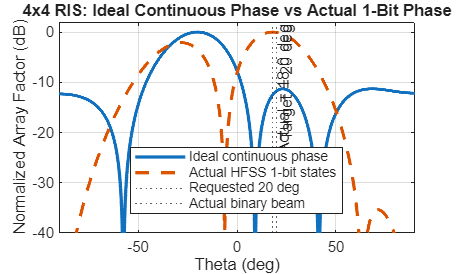



%% ========================================================================
% 9. PLOT 1
%
% IDEAL CONTINUOUS PHASE VS ACTUAL 1-BIT 4x4
%
% This is one of the most important figures for the report.
%
% It demonstrates:
%
%       ideal phase control
%              VS
%       actual two-state HFSS control
%
% ========================================================================

x4 = ...
    ((0:N-1)-(N-1)/2)*pitchX;

% Desired continuous phase profile
desiredPhase = ...
    -k*x4*sind(targetAngle);

desiredPhase_deg = ...
    rad2deg(desiredPhase);

% Wrap to [-180,180]
desiredPhase_deg = ...
    mod(desiredPhase_deg+180,360)-180;


% ------------------------------------------------------------
% Generate ideal continuous array factor
% ------------------------------------------------------------

AFideal = zeros(size(theta));

for t = 1:length(theta)

    AFideal(t) = ...
        sum( ...
        exp( ...
        1j*( ...
        desiredPhase ...
        - k*x4*sind(theta(t)))));

end

AFideal_dB = ...
    20*log10( ...
    abs(AFideal)/max(abs(AFideal)) + 1e-12);


% Actual binary pattern
actualBits = bestPattern;

actualPhase = ...
    phaseOFF*ones(1,N);

actualMagnitude = ...
    magOFF*ones(1,N);

actualPhase(actualBits==1) = phaseON;
actualMagnitude(actualBits==1) = magON;

AFactual = zeros(size(theta));

for t = 1:length(theta)

    AFactual(t) = ...
        sum( ...
        actualMagnitude .* ...
        exp( ...
        1j*( ...
        actualPhase ...
        - k*x4*sind(theta(t)))));

end

AFactual_dB = ...
    20*log10( ...
    abs(AFactual)/max(abs(AFactual)) + 1e-12);


figure( ...
    'Name','4x4 Ideal vs Actual Binary Beam', ...
    'Position',[100 100 1000 600]);

plot( ...
    theta, ...
    AFideal_dB, ...
    'LineWidth',2);

hold on;

plot( ...
    theta, ...
    AFactual_dB, ...
    '--', ...
    'LineWidth',2);

xline( ...
    targetAngle, ...
    ':', ...
    'Target = 20 deg');

xline( ...
    bestBeam, ...
    ':', ...
    sprintf('Actual = %.1f deg',bestBeam));

grid on;

xlabel('Theta (deg)');
ylabel('Normalized Array Factor (dB)');

title( ...
    '4x4 RIS: Ideal Continuous Phase vs Actual 1-Bit Phase');

legend( ...
    'Ideal continuous phase', ...
    'Actual HFSS 1-bit states', ...
    'Requested 20 deg', ...
    'Actual binary beam', ...
    'Location','best');

xlim([-90 90]);
ylim([-40 2]);

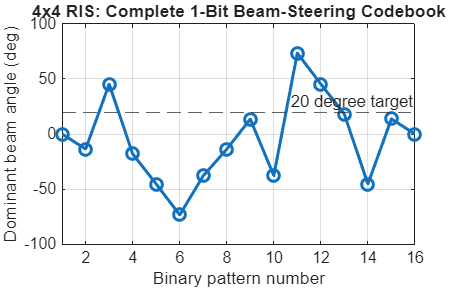



%% ========================================================================
% 10. PLOT 2
%
% COMPLETE 4x4 BINARY CODEBOOK
%
% This demonstrates that the 4x4 structure does not provide a
% continuously steerable beam.
%
% ========================================================================

figure( ...
    'Name','4x4 Binary Beam Codebook', ...
    'Position',[100 100 950 600]);

plot( ...
    1:numPatterns, ...
    codebookBeam, ...
    'o-', ...
    'LineWidth',1.8, ...
    'MarkerSize',7);

hold on;

yline( ...
    targetAngle, ...
    '--', ...
    '20 degree target');

grid on;

xlabel('Binary pattern number');

ylabel('Dominant beam angle (deg)');

title( ...
    '4x4 RIS: Complete 1-Bit Beam-Steering Codebook');

xlim([1 numPatterns]);

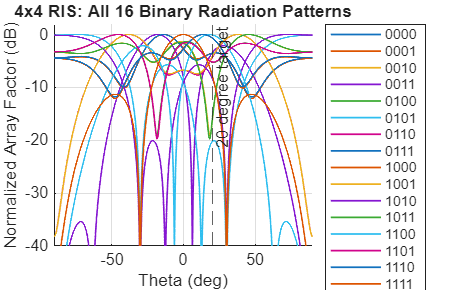



%% ========================================================================
% 11. PLOT 3
%
% ALL 16 RADIATION PATTERNS
%
% ========================================================================

figure( ...
    'Name','4x4 Complete Binary Radiation Patterns', ...
    'Position',[100 100 1100 700]);

hold on;
grid on;

for p = 1:numPatterns

    bits = codebookPattern(p,:);

    label = sprintf( ...
        '%d%d%d%d', ...
        bits(1),bits(2),bits(3),bits(4));

    plot( ...
        theta, ...
        all4x4AF{p}, ...
        'LineWidth',1.0, ...
        'DisplayName',label);

end

xline( ...
    targetAngle, ...
    '--', ...
    '20 degree target');

xlabel('Theta (deg)');

ylabel('Normalized Array Factor (dB)');

title( ...
    '4x4 RIS: All 16 Binary Radiation Patterns');

xlim([-90 90]);
ylim([-40 2]);

legend( ...
    'Location','eastoutside');



%% ========================================================================
% 12. ARRAY SCALING
%
% For N > 4, exhaustive 2^N search becomes unnecessary.
%
% Instead, we construct the physical binary approximation of the
% desired 20-degree phase ramp.
%
% Because a global phase offset does not change the radiation
% pattern, several offsets are tested and the one giving the
% strongest response at the requested target is selected.
%
% ========================================================================

beamAngleScaling = zeros(size(arraySizes));
beamErrorScaling = zeros(size(arraySizes));
beamwidthScaling = zeros(size(arraySizes));

apertureScaling = zeros(size(arraySizes));
farFieldScaling = zeros(size(arraySizes));

bestPatterns = cell(size(arraySizes));


% Global phase offsets used for binary quantization
phaseOffsets = ...
    deg2rad(0:1:359);


for a = 1:length(arraySizes)

    N = arraySizes(a);


    %% ------------------------------------------------------------
    % Physical aperture
    % ------------------------------------------------------------

    D = ...
        (N-1)*pitchX + cellX;

    apertureScaling(a) = D;

    farFieldScaling(a) = ...
        2*D^2/lambda;


    %% ------------------------------------------------------------
    % X coordinates
    % ------------------------------------------------------------

    x = ...
        ((0:N-1)-(N-1)/2)*pitchX;


    %% ------------------------------------------------------------
    % Required continuous phase
    % ------------------------------------------------------------

    desiredPhase = ...
        -k*x*sind(targetAngle);


    %% ------------------------------------------------------------
    % Search global phase offset
    %
    % Objective:
    %
    % maximize field at the requested 20-degree direction.
    % ------------------------------------------------------------

    bestTargetMagnitude = -Inf;

    bestBits = zeros(1,N);

    for p0 = 1:length(phaseOffsets)

        offset = phaseOffsets(p0);

        phaseRequired = ...
            desiredPhase + offset;


        % Circular distance to OFF state
        errorOFF = ...
            abs(angle( ...
            exp(1j*(phaseRequired-phaseOFF))));


        % Circular distance to ON state
        errorON = ...
            abs(angle( ...
            exp(1j*(phaseRequired-phaseON))));


        bits = ...
            errorON < errorOFF;


        % Physical states
        phaseState = ...
            phaseOFF*ones(1,N);

        magnitudeState = ...
            magOFF*ones(1,N);

        phaseState(bits==1) = phaseON;
        magnitudeState(bits==1) = magON;


        % Field exactly at target
        AFtarget = ...
            sum( ...
            magnitudeState .* ...
            exp( ...
            1j*( ...
            phaseState ...
            - k*x*sind(targetAngle))));


        if abs(AFtarget) > bestTargetMagnitude

            bestTargetMagnitude = abs(AFtarget);

            bestBits = bits;

        end

    end


    bestPatterns{a} = bestBits;


    %% ------------------------------------------------------------
    % Calculate complete radiation pattern
    % ------------------------------------------------------------

    phaseState = ...
        phaseOFF*ones(1,N);

    magnitudeState = ...
        magOFF*ones(1,N);

    phaseState(bestBits==1) = phaseON;
    magnitudeState(bestBits==1) = magON;


    AF = zeros(size(theta));


    for t = 1:length(theta)

        AF(t) = ...
            sum( ...
            magnitudeState .* ...
            exp( ...
            1j*( ...
            phaseState ...
            - k*x*sind(theta(t)))));

    end


    AFmag = abs(AF);


    %% ------------------------------------------------------------
    % Dominant beam
    % ------------------------------------------------------------

    [~,idxPeak] = max(AFmag);

    beamAngleScaling(a) = ...
        theta(idxPeak);

    beamErrorScaling(a) = ...
        beamAngleScaling(a)-targetAngle;


    %% ------------------------------------------------------------
    % 3-dB beamwidth around GLOBAL maximum
    % ------------------------------------------------------------

    AFdB = ...
        20*log10( ...
        AFmag/max(AFmag)+1e-12);

    leftIndex = idxPeak;

    while leftIndex > 1 && ...
            AFdB(leftIndex-1) >= -3

        leftIndex = leftIndex-1;

    end


    rightIndex = idxPeak;

    while rightIndex < length(theta) && ...
            AFdB(rightIndex+1) >= -3

        rightIndex = rightIndex+1;

    end


    beamwidthScaling(a) = ...
        theta(rightIndex)-theta(leftIndex);

end


%% ========================================================================
% 13. PRINT ARRAY-SCALING RESULTS
% ========================================================================

fprintf('\n');
fprintf('====================================================================\n');

fprintf('                 ARRAY SCALING RESULTS\n');

                 ARRAY SCALING RESULTS


fprintf('====================================================================\n');


fprintf('\n');

fprintf(['Array       Elements       Physical size       Far-field R       ' ...
         'Beam       Error       3-dB BW\n']);

Array       Elements       Physical size       Far-field R       Beam       Error       3-dB BW



fprintf(['--------------------------------------------------------------------' ...
         '------------------\n']);

--------------------------------------------------------------------------------------



for a = 1:length(arraySizes)

    N = arraySizes(a);

    fprintf( ...
        '%3dx%-3d    %8d       %10.3f m       %10.3f m    %+7.2f    %+7.2f    %8.2f\n', ...
        N,N,N^2, ...
        apertureScaling(a), ...
        farFieldScaling(a), ...
        beamAngleScaling(a), ...
        beamErrorScaling(a), ...
        beamwidthScaling(a));

end

  2x2             4            0.101 m            0.167 m      +0.00     -20.00       60.00
  4x4            16            0.223 m            0.813 m     +18.05      -1.95       26.40
  8x8            64            0.467 m            3.565 m     +19.05      -0.95       12.40
 16x16          256            0.955 m           14.907 m     +19.60      -0.40        6.30
 64x64         4096            3.883 m          246.439 m     +19.95      -0.05        1.60
256x256       65536           15.595 m         3975.082 m     +20.00      +0.00        0.35
512x512      262144           31.211 m        15921.748 m     +20.00      +0.00        0.20


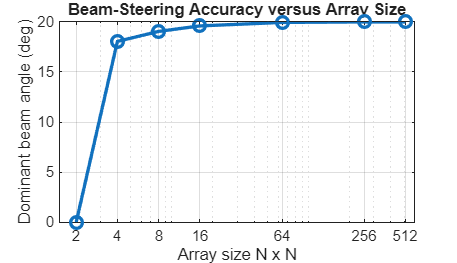



%% ========================================================================
% 14. PLOT 4
%
% ARRAY SIZE VS BEAM ANGLE
% ========================================================================

figure( ...
    'Name','Beam Angle vs Array Size', ...
    'Position',[100 100 950 550]);

semilogx( ...
    arraySizes, ...
    beamAngleScaling, ...
    'o-', ...
    'LineWidth',2, ...
    'MarkerSize',7);

hold on;

yline( ...
    targetAngle, ...
    '--', ...
    '20 degree target');

grid on;

xlabel('Array size N x N');

ylabel('Dominant beam angle (deg)');

title( ...
    'Beam-Steering Accuracy versus Array Size');

xticks(arraySizes);
xticklabels(string(arraySizes));

xlim([1.5 600]);

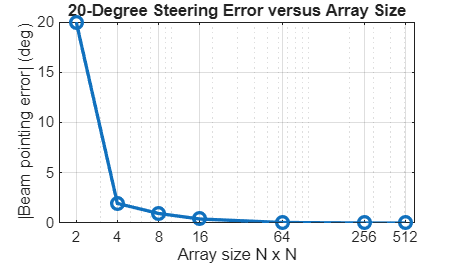



%% ========================================================================
% 15. PLOT 5
%
% POINTING ERROR VS ARRAY SIZE
%
% This is one of the most useful report figures.
% ========================================================================

figure( ...
    'Name','Beam Pointing Error vs Array Size', ...
    'Position',[100 100 950 550]);

semilogx( ...
    arraySizes, ...
    abs(beamErrorScaling), ...
    'o-', ...
    'LineWidth',2, ...
    'MarkerSize',7);

hold on;

yline( ...
    0, ...
    '--');

grid on;

xlabel('Array size N x N');

ylabel('|Beam pointing error| (deg)');

title( ...
    '20-Degree Steering Error versus Array Size');

xticks(arraySizes);
xticklabels(string(arraySizes));

xlim([1.5 600]);

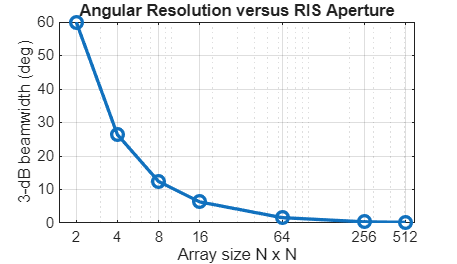



%% ========================================================================
% 16. PLOT 6
%
% BEAMWIDTH VS ARRAY SIZE
%
% A larger aperture should provide greater angular resolution.
%
% ========================================================================

figure( ...
    'Name','Beamwidth vs Array Size', ...
    'Position',[100 100 950 550]);

semilogx( ...
    arraySizes, ...
    beamwidthScaling, ...
    'o-', ...
    'LineWidth',2, ...
    'MarkerSize',7);

grid on;

xlabel('Array size N x N');

ylabel('3-dB beamwidth (deg)');

title( ...
    'Angular Resolution versus RIS Aperture');

xticks(arraySizes);
xticklabels(string(arraySizes));

xlim([1.5 600]);

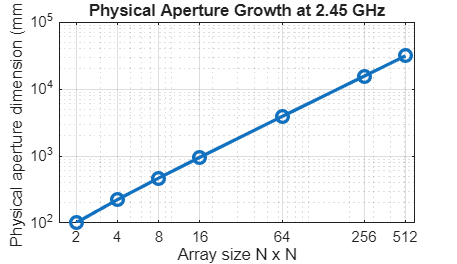



%% ========================================================================
% 17. PLOT 7
%
% PHYSICAL APERTURE VS ARRAY SIZE
%
% This makes the scaling study genuinely real-world.
%
% ========================================================================

figure( ...
    'Name','Physical Aperture Scaling', ...
    'Position',[100 100 950 550]);

loglog( ...
    arraySizes, ...
    apertureScaling*1e3, ...
    'o-', ...
    'LineWidth',2, ...
    'MarkerSize',7);

grid on;

xlabel('Array size N x N');

ylabel('Physical aperture dimension (mm)');

title( ...
    'Physical Aperture Growth at 2.45 GHz');

xticks(arraySizes);
xticklabels(string(arraySizes));

xlim([1.5 600]);

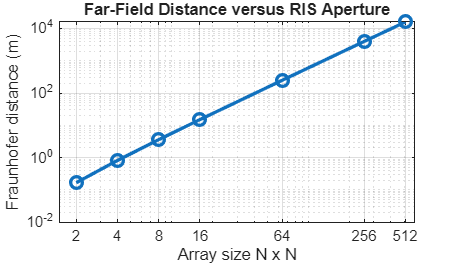



%% ========================================================================
% 18. PLOT 8
%
% FAR-FIELD DISTANCE VS ARRAY SIZE
%
% R_FF = 2D^2/lambda
%
% This is important because the radiation pattern should be evaluated
% in the far field.
%
% ========================================================================

figure( ...
    'Name','Far Field Distance Scaling', ...
    'Position',[100 100 950 550]);

loglog( ...
    arraySizes, ...
    farFieldScaling, ...
    'o-', ...
    'LineWidth',2, ...
    'MarkerSize',7);

grid on;

xlabel('Array size N x N');

ylabel('Fraunhofer distance (m)');

title( ...
    'Far-Field Distance versus RIS Aperture');

xticks(arraySizes);
xticklabels(string(arraySizes));

xlim([1.5 600]);

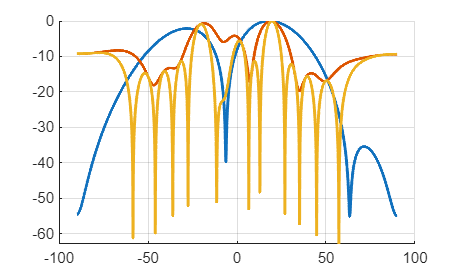

Unable to perform assignment with 0 elements on the right-hand side.



%% ========================================================================
% 19. PLOT 9
%
% REPRESENTATIVE BEAM PATTERNS
%
% Compare:
%
%       4x4
%       8x8
%       16x16
%
% These are the most useful scaling cases for your report.
% ========================================================================

representativeArrays = [4 8 16 1024];

figure( ...
    'Name','Representative Beam Scaling', ...
    'Position',[100 100 1000 600]);

hold on;
grid on;

for r = 1:length(representativeArrays)

    N = representativeArrays(r);

    a = find(arraySizes==N,1);

    x = ...
        ((0:N-1)-(N-1)/2)*pitchX;

    bits = ...
        bestPatterns{a};

    phaseState = ...
        phaseOFF*ones(1,N);

    magnitudeState = ...
        magOFF*ones(1,N);

    phaseState(bits==1) = phaseON;
    magnitudeState(bits==1) = magON;

    AF = zeros(size(theta));

    for t = 1:length(theta)

        AF(t) = ...
            sum( ...
            magnitudeState .* ...
            exp( ...
            1j*( ...
            phaseState ...
            - k*x*sind(theta(t)))));

    end

    AFdB = ...
        20*log10( ...
        abs(AF)/max(abs(AF))+1e-12);

    plot( ...
        theta, ...
        AFdB, ...
        'LineWidth',1.8, ...
        'DisplayName', ...
        sprintf('%dx%d',N,N));

end


xline( ...
    targetAngle, ...
    '--', ...
    '20 degree target');

xlabel('Theta (deg)');

ylabel('Normalized Array Factor (dB)');

title( ...
    'Binary RIS Beam Pattern: Effect of Aperture');

xlim([-90 90]);
ylim([-40 2]);

legend('Location','best');


%% ========================================================================
% 20. FINAL ENGINEERING INTERPRETATION
% ========================================================================

fprintf('\n');
fprintf('====================================================================\n');
fprintf('                     ENGINEERING CONCLUSION\n');
fprintf('====================================================================\n');

fprintf('\n');

fprintf(['1. The 4x4 RIS DOES produce directional scattering for some\n' ...
         '   binary configurations. Therefore it is incorrect to state\n' ...
         '   that a 4x4 RIS cannot beam steer at all.\n']);

fprintf('\n');

fprintf(['2. However, the 4x4 array has only 16 X-direction binary\n' ...
         '   configurations. Its available beams are therefore discrete\n' ...
         '   rather than continuously steerable.\n']);

fprintf('\n');

fprintf(['3. For the requested 20-degree direction, the closest 4x4\n' ...
         '   binary configuration produces approximately %+6.2f degrees\n' ...
         '   in this coordinate convention.\n'],bestBeam);

fprintf('\n');

fprintf(['4. The resulting beam is broad because the physical aperture\n' ...
         '   contains only four elements along the steering direction.\n']);

fprintf('\n');

fprintf(['5. Increasing the number of elements increases the physical\n' ...
         '   aperture and improves angular resolution. The beamwidth,\n' ...
         '   pointing error and physical aperture are therefore studied\n' ...
         '   together rather than considering beam angle alone.\n']);

fprintf('\n');

fprintf(['6. The 64x64, 256x256 and 512x512 cases are analytical scaling\n' ...
         '   cases. At 2.45 GHz their physical dimensions and required\n' ...
         '   far-field distances become very large.\n']);

fprintf('\n');

fprintf(['7. Consequently, the 4x4 HFSS result is not treated as a failed\n' ...
         '   RIS. It demonstrates the spatial-control limitation of the\n' ...
         '   present small 1-bit aperture.\n']);

fprintf('\n');

fprintf(['8. The next stage should therefore NOT attempt to force a\n' ...
         '   20-degree far-field beam from the 4x4 structure. The next\n' ...
         '   stage should evaluate the actual project objective:\n' ...
         '   RIS-assisted TX-RX signal improvement.\n']);

fprintf('\n');

fprintf('====================================================================\n');
fprintf('                         END OF STUDY\n');
fprintf('====================================================================\n');